clear
parallel.gpu.enableCUDAForwardCompatibility(true)
canUseGPU

ans = logical
   1


gpuDevice

ans =   CUDADevice with properties:

                 Name: 'NVIDIA RTX PRO 2000 Blackwell Generation Laptop GPU'
                Index: 1 (of 1)
    ComputeCapability: '12.0'
          DriverModel: 'WDDM'
          TotalMemory: 8546549760 (8.55 GB)
      AvailableMemory: 7338979328 (7.34 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

run("winedata.m")

reviewText = winemag_data_first150k.description;
documents = tokenizedDocument(reviewText);
documents = lower(documents);
documents = removeStopWords(documents);
bag = bagOfWords(documents)

bag =   bagOfWords with properties:

        NumWords: 41427
          Counts: [150930×41427 double]
      Vocabulary: ["tremendous"    "100"    "%"    "varietal"    "wine"    "hails"    "oakville"    "aged"    "three"    "years"    "oak"    "."    "juicy"    "red-cherry"    "fruit"    "compelling"    "hint"    "caramel"    …    ] (1×41427 string)
    NumDocuments: 150930


X = tfidf(bag);

size(X)

ans =       150930       41427


nnz(X)

ans = 3961510

elements = 50;
[U, S, V] = svds(X, elements);
Z = U*S;

vocab = bag.Vocabulary;
pc1 = V(:,1);
pc2 = V(:,2);

[~, idxPos] = sort(pc1, 'descend');
topPosWords_pc1 = vocab(idxPos(1:15))

topPosWords_pc1 = 1×15 string array
    "%"    "fruit"    "wine"    "black"    "tannins"    "finish"    "aromas"    "cherry"    "flavors"    "palate"    "ripe"    "acidity"    "spice"    "drink"    "red"



[~, idxNeg] = sort(pc1, 'ascend');
topNegWords_pc1 = vocab(idxNeg(1:15))

topNegWords_pc1 = 1×15 string array
    "judi"    "flom"    "sorensen"    "gluey-sweet"    "mawkish"    "strawberry-banana"    "thin-flavored"    "dill-flavored"    "harvett"    "giant-sized"    "altough"    "cherry-coffee"    "andflat"    "donut-y"    "simple-fruity"


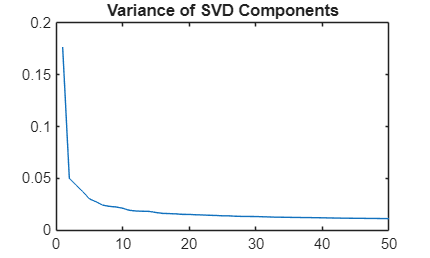

figure
singVals = diag(S).^2;
explained = singVals / sum(singVals);
plot(explained(1:50));
title("Variance of SVD Components");

labels = categorical(winemag_data_first150k.variety);
[vals,~,idx] = unique(labels);
counts = histcounts(idx, 1:numel(vals)+1);
[~,order] = sort(counts, 'descend');
topN = 6;
keepVarieties = vals(order(1:topN))

keepVarieties = 6×1 categorical array
     Chardonnay 
     Pinot Noir 
     Cabernet Sauvignon 
     Red Blend 
     Bordeaux-style Red Blend 
     Sauvignon Blanc 



mask = ismember(labels, keepVarieties);
Zsmall = Z(mask, :);
labelSmall = removecats(labels(mask));

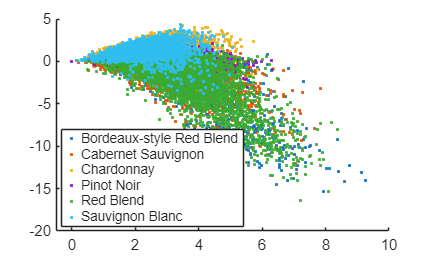

figure
gscatter(Zsmall(:,1), Zsmall(:,2), labelSmall);

figure
scatter3(Zsmall(:,1),Zsmall(:,2),Zsmall(:,3),1,labelSmall)

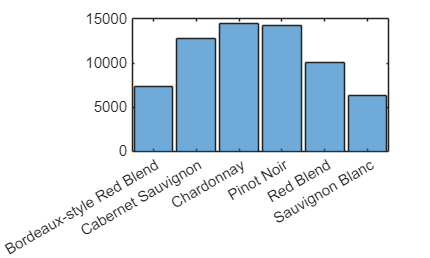

features = Zsmall(:,1:elements);
histogram(labelSmall)

textSmall  = winemag_data_first150k.description(mask);
labelSmall = removecats(labels(mask));

cv = cvpartition(labelSmall,'HoldOut',0.2);

Xtrain = features(training(cv), :)

Xtrain =     4.8611   -3.5920    0.0487    0.5467   -0.2948   -0.9257   -2.5738   -0.0806   -0.5934   -2.5524    2.2260   -0.3621   -0.8920   -2.0489   -0.2277   -1.2286    1.0787    3.3193   -0.4284    1.1175   -2.0141   -1.0551    0.3281    0.5470   -0.7291    0.2475   -0.4429   -0.2788   -0.0117   -1.3783   -0.4736   -0.4699   -1.4717   -0.3186    0.4732   -0.3169   -0.3851   -1.2724   -1.1232   -0.4212    0.2778   -0.7973    0.3996   -0.6316   -0.4088    0.7168   -0.7210    0.0531    0.8112    0.2155
    2.7603    0.6426   -0.1015   -1.0297   -0.0306    0.9530    0.2186    1.1526    0.9450   -0.6164    1.7170   -2.3690   -1.3258    1.1200    0.1641   -0.3450    0.4285   -1.3197    0.6929    0.6345   -0.3820   -1.1367    0.0930   -1.1307    1.0390    0.2260    0.9480   -0.2137    0.2457    0.7878   -0.9435    0.0579   -0.7386   -0.8925    0.8615    0.5052    0.9830    0.4543   -0.8109   -1.0129   -0.1467    0.8618    1.1520   -0.8475    0.9579   -0.5285   -0.4018   -0.4122   -0.7039

Xtest = features(test(cv), :)

Xtest =     4.2225   -1.8515    0.2714   -1.9516   -0.4496   -0.7143   -0.3211    2.7510   -1.8839   -1.9622    0.9216    0.7335    1.4146   -0.7182    1.7188    1.1581    1.0173    0.4166   -0.1483   -0.4502   -0.1417   -1.1513   -0.2626    0.0887    0.2168    2.6007   -0.5439   -0.0048   -0.4711    0.2191    0.5296    0.2093   -0.6927   -0.2741   -0.2435    0.9585    0.0433   -0.2060   -0.1321    0.1864    1.0370   -0.4204   -0.6568   -0.4620    0.0305    0.4408   -0.3330   -0.5609    0.0888    0.5086
    2.4069    1.1692   -1.0214   -0.7934   -0.1554    0.6963   -1.3242    0.1697   -0.2465   -1.0129   -0.9809   -1.5177   -0.7426   -0.0840   -0.3613   -0.6622   -0.7752   -1.0731   -0.8732   -1.5058   -0.8255   -0.8248    1.7772   -0.0195    0.7147    0.5775   -0.2600    0.0028   -1.6510    0.1230    0.1014    0.4034   -1.5443    0.0261    0.2708   -1.5585   -0.5982   -1.7728   -0.4467   -0.2574   -0.1706    0.3352    0.6095    1.2646    1.1084    0.0855   -1.1387    0.0736    0.9600 


%XtrainText = string(textSmall(training(cv)));
Ytrain     = labelSmall(training(cv));

%XtestText  = string(textSmall(test(cv)));
Ytest      = labelSmall(test(cv));

mdl = fitcecoc(Xtrain, Ytrain);  % multiclass SVM

Ypred = predict(mdl, Xtest);

accuracy_svm = mean(Ypred == Ytest);
disp(accuracy_svm);

    0.8016



countcats(Ypred)

ans =         1269
        2777
        3172
        2980
        1841
        1021


categories(Ypred)

ans = 6×1 cell array
    {'Bordeaux-style Red Blend'}
    {'Cabernet Sauvignon'      }
    {'Chardonnay'              }
    {'Pinot Noir'              }
    {'Red Blend'               }
    {'Sauvignon Blanc'         }


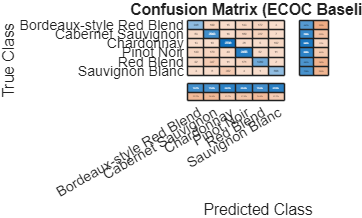


[C, order] = confusionmat(Ytest, Ypred);
figure
cm_ecoc = confusionchart(C, order);
cm_ecoc.Title = 'Confusion Matrix (ECOC Baseline)';
cm_ecoc.RowSummary = 'row-normalized';
cm_ecoc.ColumnSummary = 'column-normalized';

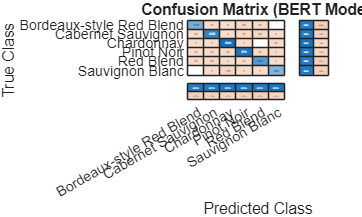

run("getBERTConfusionList.m")
run("getBERTConfusionMatrix.m")
figure
cm_bert = confusionchart(confusion_matrix, confusion_matrix_labels);
cm_bert.Title = 'Confusion Matrix (BERT Model)';
cm_bert.RowSummary = 'row-normalized';
cm_bert.ColumnSummary = 'column-normalized';

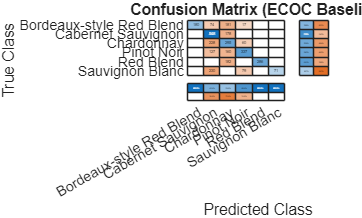

figure
cm = confusionchart(max((ones(6,6) - eye(6,6))*(C-confusion_matrix),zeros(6,6)), confusion_matrix_labels);
cm.Title = 'Confusion Matrix (ECOC Baseline)';
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';